close all hidden; clear; clc;
rng(418);                                  % seed for reproducibility, 

## 1.e  Unconstrained MPC simulation

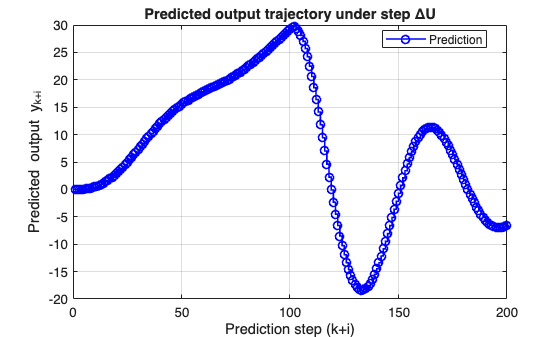

clear; clc; close all;

% System parameters
m = 1; c = 0.4; k = 1; T = 0.1;
A = [1 T; -k/m*T 1 - (c/m)*T];
B = [0; T/m];
C = [1 0];

% Horizons and weights
Np = 200; Nc = 100;
Qbar = eye(Np); 
Rbar = 0.1 * eye(Nc);

% F and H matrices
F = zeros(Np, size(A,1));
Ap = A;
for i = 1:Np
    F(i,:) = C * Ap;
    Ap = Ap * A;
end

H = zeros(Np, Nc);
for i = 1:Np
    for j = 1:Nc
        if j <= i
            H(i,j) = C * (A^(i-j)) * B;
        else
            H(i,j) = 0;
        end
    end
end

% S and Phi matrices
S = tril(ones(Nc));     
Phi = H * S;            

% Step pattern for ΔU
DeltaU = 0.3 * ones(Nc, 1);   
% step change, saturating at ±0.3

% Initial conditions
xk = [0; 0]; 
u_prev = 0;
u_b = u_prev * ones(Nc,1);
bk = F*xk + H*u_b;

% Predicted output (Y = b_k + ΦΔU)
Ypred = bk + Phi * DeltaU;

% Plot predicted trajectory
figure('Color','w');
stairs(1:Np, Ypred, 'b-o','LineWidth',1.2); hold on; grid on;
xlabel('Prediction step (k+i)');
ylabel('Predicted output y_{k+i}');
title('Predicted output trajectory under step ΔU');
legend('Prediction','Location','best');